# K-MEANS

## Reflection


im = Reflection;
[rows, cols, bands] = size(im);
reshaped = reshape(im, rows * cols, bands);
% Set the number of clusters
numClusters = 6;

% Perform K-means clustering
[idx, C] = kmeans(reshaped, numClusters, 'Replicates', 5);

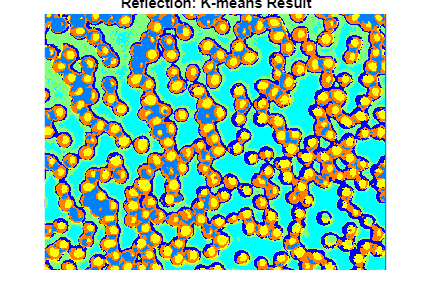


% Reshape the cluster indices back into the original image size
clusteredImage = reshape(idx, rows, cols);

% Visualize the clustered image
figure;
imshow(label2rgb(clusteredImage), []);
title('Reflection: K-means Result');

## Transmission


im = Transmission;
[rows, cols, bands] = size(im);
reshaped = reshape(im, rows * cols, bands);
% Set the number of clusters
numClusters = 6;

% Perform K-means clustering
[idx, C] = kmeans(reshaped, numClusters, 'Replicates', 5);

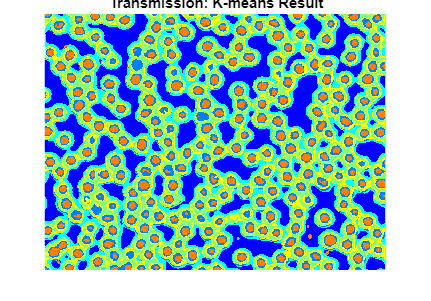


% Reshape the cluster indices back into the original image size
clusteredImage = reshape(idx, rows, cols);

% Visualize the clustered image
figure;
imshow(label2rgb(clusteredImage), []);
title('Transmission: K-means Result');

## Scattering


im = Scattering;
[rows, cols, bands] = size(im);
reshaped = reshape(im, rows * cols, bands);
% Set the number of clusters
numClusters = 7; %%one additional cluster for the noise

% Perform K-means clustering
[idx, C] = kmeans(reshaped, numClusters, 'Replicates', 5);

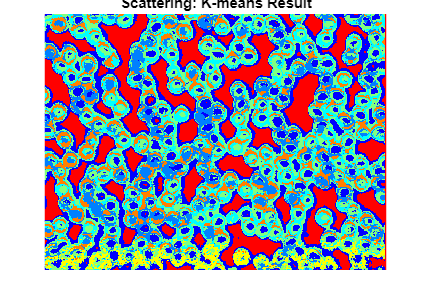


% Reshape the cluster indices back into the original image size
clusteredImage = reshape(idx, rows, cols);

% Visualize the clustered image
figure;
imshow(label2rgb(clusteredImage), []);
title('Scattering: K-means Result');